# Geom 3D suspension model test

In this script I am just playing around with the capabilities of the geom3d toolbox for doing suspension geometry related things, you can check out the capabilities and function in the toolbox at [https://uk.mathworks.com/matlabcentral/fileexchange/24484-geom3d](https://uk.mathworks.com/matlabcentral/fileexchange/24484-geom3d)

close all, clear, clc

## If you don't have the geom2d and geom3d toolboxes installed we will need to do them first

if ~exist('isAxisHandle','file')
    disp('Geom2d toolbox not found')
    disp('Downloading Geom2d toolbox')
    websave('geom2d.mltbx','https://uk.mathworks.com/matlabcentral/mlc-downloads/downloads/submissions/7844/versions/27/download/mltbx');
    disp('Installing Geom2d toolbox')
    matlab.addons.toolbox.installToolbox('geom2d.mltbx');
    delete('geom2d.mltbx');
    disp('Geom2d toolbox installed!')
end

if ~exist('createLine3d','file')
    disp('Geom3d toolbox not found')
    disp('Downloading Geom3d toolbox')
    websave('geom3d.mltbx','https://uk.mathworks.com/matlabcentral/mlc-downloads/downloads/e564dff6-4a80-11e4-9553-005056977bd0/b0eccf7a-b5a7-4ba4-8d09-39644cf7fb38/packages/mltbx');
    disp('Installing Geom3d toolbox')
    matlab.addons.toolbox.installToolbox('geom3d.mltbx');
    delete('geom3d.mltbx');
    disp('Geom3d toolbox installed!')
end

## Define the points

% Front right suspension
geom.front.right.points.UB = [23.0655673 534.9614419 259];
geom.front.right.points.LB = [4.91527695 565.0048038 100];
geom.front.right.points.OS = [22.44361554 500.833 269.866];
geom.front.right.points.OT = [72.75746352 510.7477082 212.5];
geom.front.right.points.CP = [0 600 0];
geom.front.right.points.WC = [0 600 184.15];
geom.front.right.points.WF = [-184.15 600 184.15];
geom.front.right.points.UIF = [-90 255.7718044 183.9763999];
geom.front.right.points.UIR = [122 251.2511334 175.4741666];
geom.front.right.points.LIF = [-112 198.237626 75.7692321];
geom.front.right.points.LIR = [81 203.9560591 86.52415151];
geom.front.right.points.IT = [72.03158434 231 149.0884239];
geom.front.right.points.IS = [22.44361554 270 346.1];

% Rear right suspension
geom.rear.right.points.UB = [1552 528.5310 266.7830];
geom.rear.right.points.OT = [1610 565 157.8050];
geom.rear.right.points.LB = [1.5292e+03 558 98];
geom.rear.right.points.OS = [1552 506.4470 275.4450];
geom.rear.right.points.CP = [1530 600 0];
geom.rear.right.points.WC = [1530 600 184.15];
geom.rear.right.points.WF = [1530-184.15 600 184.15];
geom.rear.right.points.UIF = [1366 304.898 183.637];
geom.rear.right.points.UIR = [1542 210 158.563];
geom.rear.right.points.LIF = [1366 261.089 101.246];
geom.rear.right.points.LIR = [1542 180 89.866];
geom.rear.right.points.IT = [1542 180 109.866];
geom.rear.right.points.IS = [1552 207.312 387.56];


## Build the front and rear right corners (i.e generate all the members, planes and axes)

% Build the front right suspension
geom.front.right = buildCorner(geom.front.right);

% Build the rear right suspension
geom.rear.right = buildCorner(geom.rear.right);


## Create a new 3D figure that we will plot our suspension in

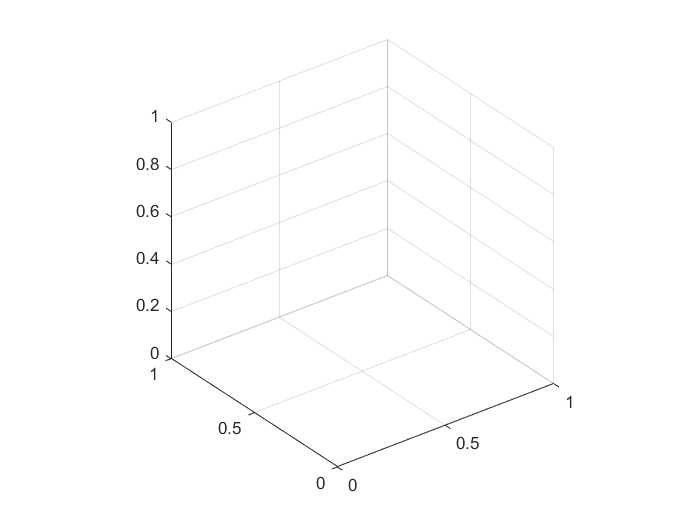

figure, hold on, grid on, view(3), axis equal

## Plot spheres at the suspension points

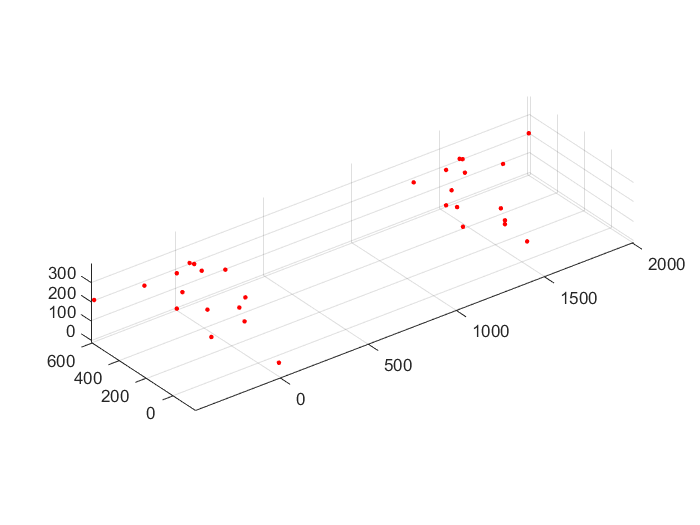

pointplotfun = @(x)drawSphere(x,10, 'facecolor', 'r');
structfun(pointplotfun,geom.front.right.points)
structfun(pointplotfun,geom.rear.right.points)

## Plot the members

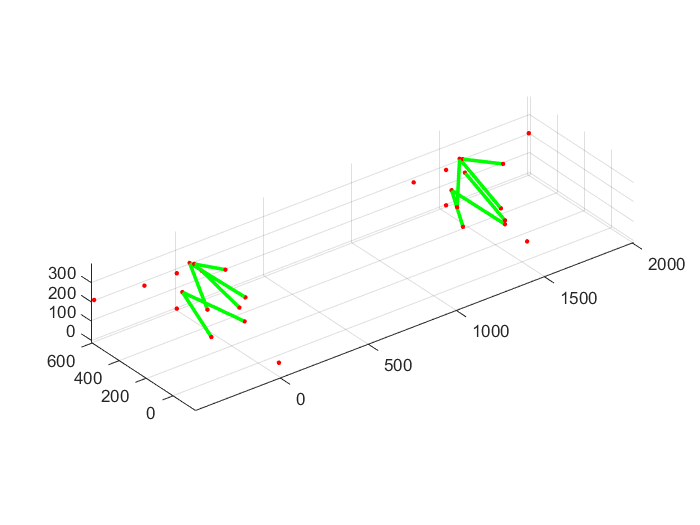

memberPlotFun = @(x)drawCylinder([x.edge,8]);
structfun(memberPlotFun,geom.front.right.members)
structfun(memberPlotFun,geom.rear.right.members)

## Plot the planes

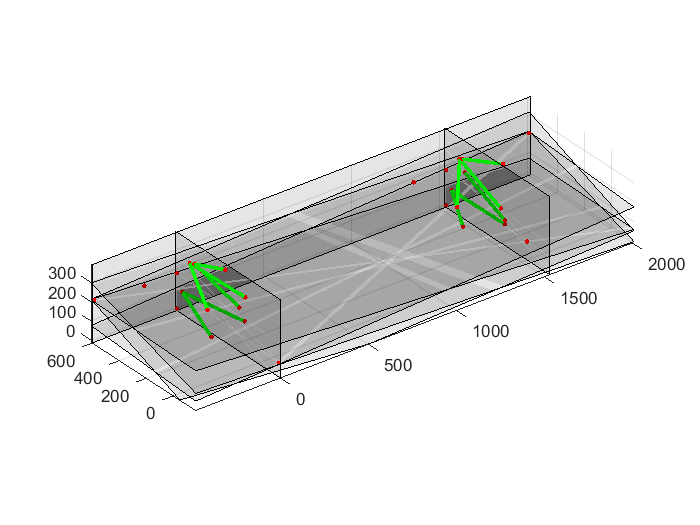

planePlotFun = @(x)drawPlane3d(x,'FaceAlpha',0.1,'EdgeColor','k');
structfun(planePlotFun,geom.front.right.planes)
structfun(planePlotFun,geom.rear.right.planes)

## Plot the axes

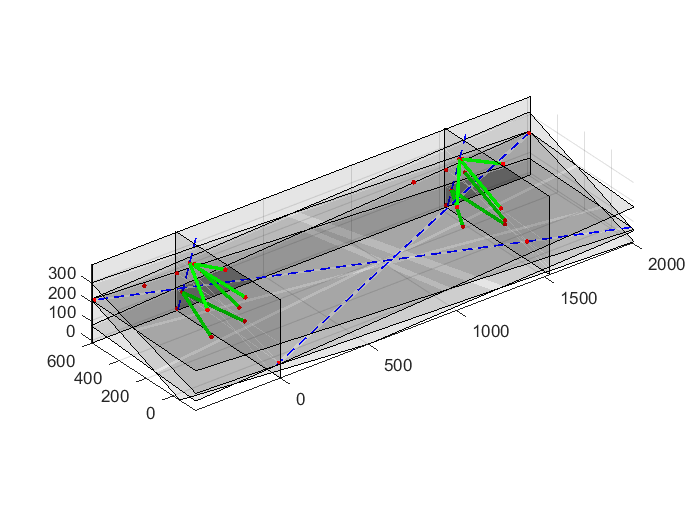

axesPlotFun = @(x)drawLine3d(x,'LineStyle','--','LineWidth',1);
structfun(axesPlotFun,geom.front.right.axes)
structfun(axesPlotFun,geom.rear.right.axes)

## Create the mirrored geometry

% Create the front left suspension
geom.front.left = mirrorCorner(geom.front.right);

% Create the rear left suspension
geom.rear.left = mirrorCorner(geom.rear.right);

## Plot both mirrored suspension geometries

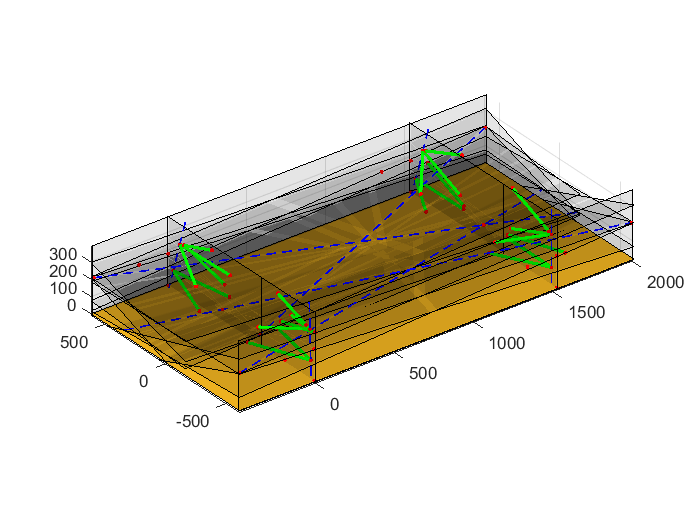

% Plot spheres at the suspension points
structfun(pointplotfun,geom.front.left.points)
structfun(pointplotfun,geom.rear.left.points)

% Plot the members
structfun(memberPlotFun,geom.front.left.members)
structfun(memberPlotFun,geom.rear.left.members)

% Plot the axes
structfun(axesPlotFun,geom.front.left.axes)
structfun(axesPlotFun,geom.rear.left.axes)

% Plot the planes
structfun(planePlotFun,geom.front.left.planes)
structfun(planePlotFun,geom.rear.left.planes)

% Plot a ground plane
drawPlane3d(createPlane(geom.front.right.points.CP,[0,0,1]),'facecolor','#EDB120')